%Inicjalizacja i wczytanie pliku
%%
clear all; close all; clc;
%%
[data, Fs] = audioread('07.wav');
N = length(data);

%Inicjalizacja parametrów EWLS i modelu AR
r = 4;  % Rząd modelu AR
lambda = 0.95; % Czynnik zapominania
P = 10000 * eye(r); % Macierz kowariancji
theta = zeros(r, 1); % Współczynniki AR

%Inicjalizacja zmiennych przechowujących wartości estymowane i błędy
theta_s = zeros(r, N);
e_residuals = zeros(1, N);

%Parametry okna do detekcji błędów
std_window = 80; % Długość okna do obliczania lokalnego odchylenia std
threshold_factor = 2.5; %Maksymalne odchylenie próbki

%EWLS i detekcja błędów

clean_signal = data; % Kopia sygnału do oczyszczenia

for t = r+1:N
    % Tworzenie wektora regresji (przeszłe wartości sygnału)
    phi = data(t-1:-1:t-r);

    % Błąd predykcji
    e = data(t) - ((phi') * theta);
    e_residuals(t) = e;

    % Aktualizacja współczynników AR za pomocą EWLS
    k = (P * phi) / (lambda + ((phi') * P * phi));
    theta = theta + k * e;
    P = (P - (k * (phi') * P)) / lambda;

    % Zapisujemy współczynniki do analizy
    theta_s(:, t) = theta;

    % Detekcja zakłóceń impulsowych
    if t > std_window
        local_std = std(e_residuals(t-std_window:t-1)); % Lokalne odchylenie std błędu
        if abs(e) > threshold_factor * local_std
            clean_signal(t) = 0.5 * (clean_signal(t-1) + clean_signal(t+1)); % Interpolacja
        end
    else
        local_std = std(e_residuals());
    end
end

%Zapis odszumionego sygnału
audiowrite('06_odszumione.wav', clean_signal, Fs);

%Wyświetlenie parametrów
fprintf('=== Parametry algorytmu ===\n');  

=== Parametry algorytmu ===


fprintf('Częstotliwość próbkowania: %d Hz\n', Fs);  

Częstotliwość próbkowania: 22050 Hz


fprintf('Liczba próbek: %d\n', N);  

Liczba próbek: 429974


fprintf('Rząd modelu AR: %d\n', r);  

Rząd modelu AR: 4


fprintf('Czynnik zapominania (lambda): %.3f\n', lambda);  

Czynnik zapominania (lambda): 0.950


fprintf('Długość okna do obliczania odchylenia std: %d\n', std_window);  

Długość okna do obliczania odchylenia std: 80


fprintf('Próg detekcji zakłóceń: %.1f * lokalne odchylenie std\n', threshold_factor);  

Próg detekcji zakłóceń: 2.5 * lokalne odchylenie std


fprintf('Plik wynikowy zapisany jako: 06_odszumione.wav\n');  

Plik wynikowy zapisany jako: 06_odszumione.wav


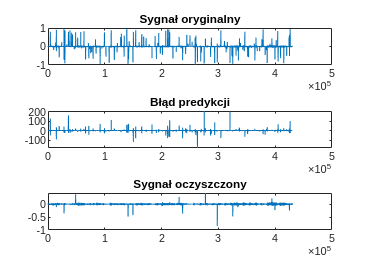


%Wizualizacja wyników  
figure;  
subplot(3,1,1);  
plot(data);  
title('Sygnał oryginalny');  

subplot(3,1,2);  
plot(e_residuals);  
title('Błąd predykcji');  

subplot(3,1,3);  
plot(clean_signal);  
title('Sygnał oczyszczony');  

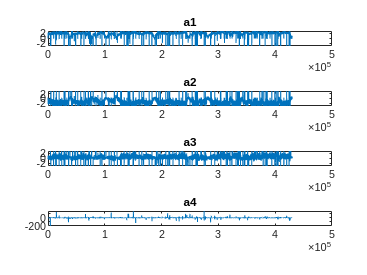


figure;
subplot(4,1,1);
plot(theta_s(1,:));
ylim([-3, 3]);
title('a1');

subplot(4,1,2);
plot(theta_s(2,:));
ylim([-3, 3]);
title('a2');

subplot(4,1,3);
plot(theta_s(3,:));
ylim([-3, 3]);
title('a3');

subplot(4,1,4);
plot(theta_s(4,:));
title('a4');